# Classify Objects with Pretrained Network

In this exercise, you will explore different pretrained networks and see how they classify different objects. 

## Choose a Pretrained Network

[net, classNames] = imagePretrainedNetwork("alexnet");

## Inspect the Network

% Inspect network's layers
% analyzeNetwork(net);
net.Layers

## Classify the Images in the Folder

Try reading in a few of the images and display them

im = imread(['02-Images',filesep,'file01.jpeg']);

ans =   24×1 Layer array with layers:

     1   'data'    Image Input                   227×227×3 images with 'zerocenter' normalization
     2   'conv1'   2-D Convolution               96 11×11×3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'   ReLU                          ReLU
     4   'norm1'   Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'   2-D Max Pooling               3×3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'   2-D Grouped Convolution       2 groups of 128 5×5×48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'   ReLU                          ReLU
     8   'norm2'   Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'   2-D Max Pooling               3×3 max pooling with stride [2  2] and padding [0  0  0  0]
 

imshow(im)

Based on your network, you'll have to look at the first layer to determine how to resize your image. Use the following command to see input size

inputSize = net.Layers(1).InputSize

`Resize your the images and classify them.`

im = imresize(im, inputSize(1:2));

score = predict(net, single(im));

inputSize =    227   227     3


label = scores2label(score, classNames);

title(char(label))

## Run this for multiple images in a folder using imageDatastore

A datastore can be used when we have lots of images that we can't load into memory at once. It serves as a way to point to a collection of images when we need them without reading them directly into MATLAB at once. (See [imageDatastore documentation](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.html) for more details)

You can manage and read images with the datastore:

- `hasdata: `determines if data is available to read

- `read`: imports images one-by-one in consecutive order (used for loops)

- `readimage`: imports a select image

- `readall`: imports all images

Create the datastore for the entire image directory. 

imgPath = '02-Images';
imds = imageDatastore(imgPath)

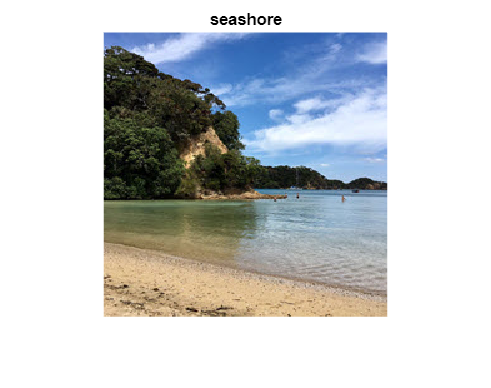

tiledlayout(4,3)


while hasdata(imds)

im = read(imds);
im = imresize(im, inputSize(1:2));

score = predict(net, single(im));
label = scores2label(score, classNames);

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\ExerciseFiles\2-PretrainedModels\02-Images\file01.jpeg';
                              ' ...\ExerciseFiles\2-PretrainedModels\02-Images\file02.jpeg';
                              ' ...\ExerciseFiles\2-PretrainedModels\02-Images\file03.jpeg'
                               ... and 9 more
                              }
                     Folders: {
                              ' ...\Deep learning Workshop Edu\ExerciseFiles\2-PretrainedModels\02-Images'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


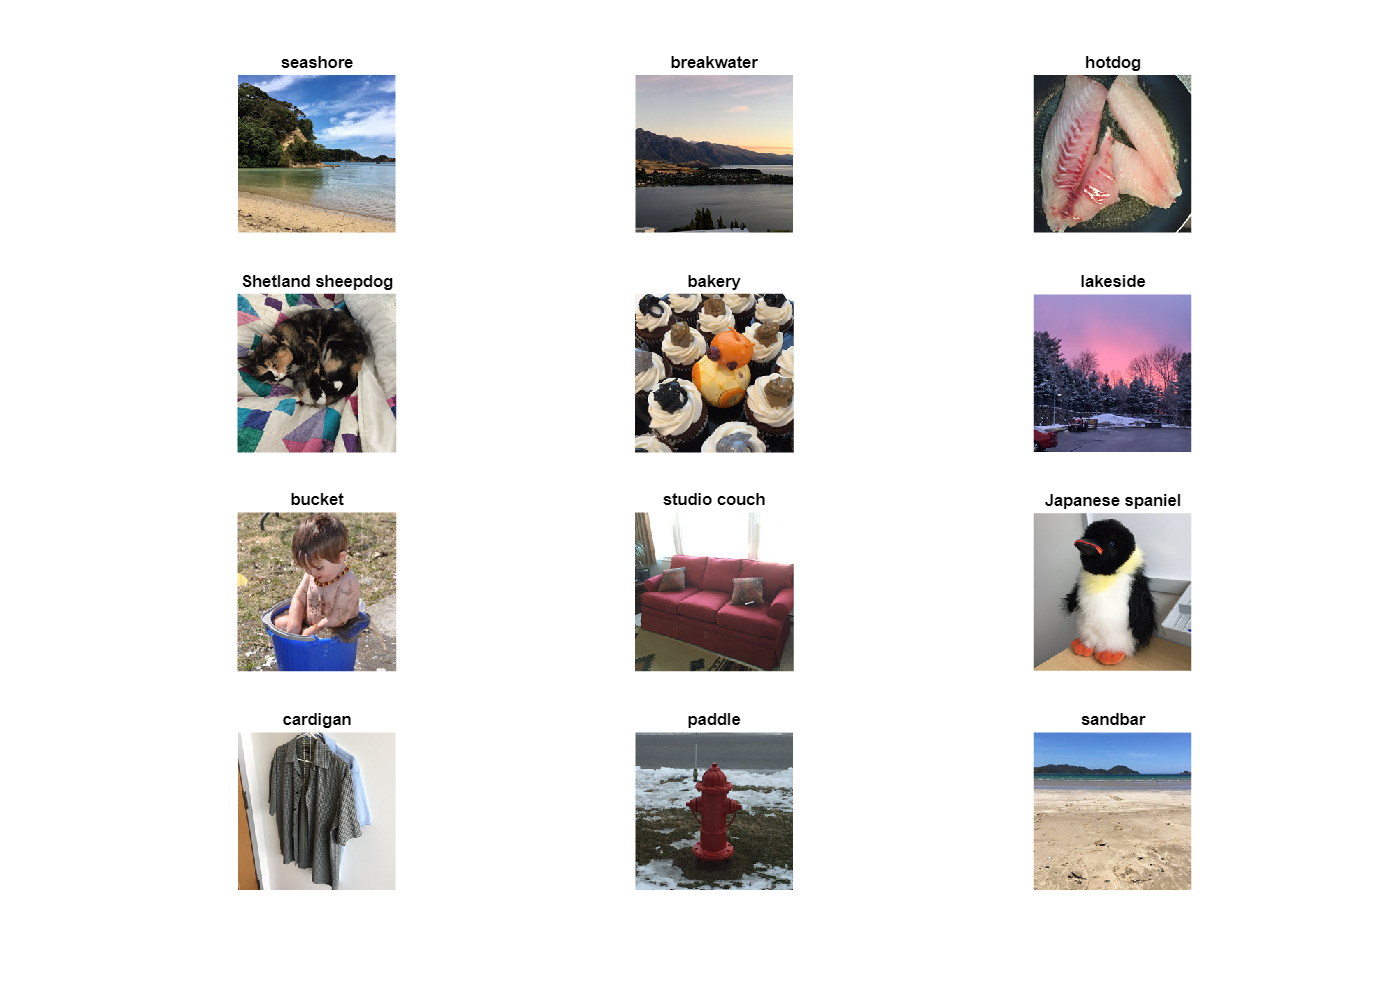


nexttile
imshow(im)
title(label)

end

*Copyright 2024 The MathWorks, Inc.*